# Load Data

load(['RSdataSteadyFlight.mat']);
secs = rt_tout(end);
%Motor Speeds
motors = squeeze(rt_MotorVelocities.signals.values);
motor1 = motors(1,:);
motor2 = motors(2,:);
motor3 = motors(3,:);
motor4 = motors(4,:);
%Angular Rates
pout = squeeze(rt_p.signals.values);
qout = squeeze(rt_q.signals.values);
rout = squeeze(rt_r.signals.values);
%Accelerations
du_out = squeeze(rt_du.signals.values);
dv_out = squeeze(rt_dv.signals.values);
dw_out = squeeze(rt_dw.signals.values);
%Roll-Pitch-Yaw Angles
phi_out = squeeze(rt_phi.signals.values);
theta_out = squeeze(rt_theta.signals.values); 
psi_out = squeeze(rt_psi.signals.values);
%Velocities
u_out = squeeze(rt_u.signals.values);
v_out = squeeze(rt_v.signals.values);
w_out = squeeze(rt_w.signals.values);
%Position
x_out = squeeze(rt_x.signals.values);
y_out = squeeze(rt_y.signals.values);
z_out = squeeze(rt_z.signals.values);
%OF Velocity
OFu = squeeze(rt_OFu.signals.values);
OFv = squeeze(rt_OFv.signals.values);
OFw = squeeze(rt_OFw.signals.values);
%OF Position
OFx = squeeze(rt_OFx.signals.values);
OFy = squeeze(rt_OFy.signals.values);
OFz = squeeze(rt_OFz.signals.values);
%Altitude
Alt = squeeze(rt_AltSignal.signals.values);
AltUnfilt = squeeze(rt_AltUnfilt.signals.values);
%TEAR
throttle = squeeze(rt_Throttle.signals.values);
elevator = squeeze(rt_Elevator.signals.values);
aileron = squeeze(rt_Aileron.signals.values);
rudder = squeeze(rt_Rudder.signals.values);
%Kalman
zK = squeeze(rt_KalmanStates.signals.values(:,1));
wK = squeeze(rt_KalmanStates.signals.values(:,2));
uK = squeeze(rt_KalmanStates.signals.values(:,3));
thetaK = squeeze(rt_KalmanStates.signals.values(:,4));
phiK = squeeze(rt_KalmanStates.signals.values(:,5));
vK = squeeze(rt_KalmanStates.signals.values(:,6));
xK = squeeze(rt_xK.signals.values);
yK = squeeze(rt_yK.signals.values);
zKi = squeeze(rt_zK.signals.values);
%Wiener
zW = squeeze(rt_WienerStates.signals.values(:,1));
wW = squeeze(rt_WienerStates.signals.values(:,2));
uW = squeeze(rt_WienerStates.signals.values(:,3));
thetaW = squeeze(rt_WienerStates.signals.values(:,4));
phiW = squeeze(rt_WienerStates.signals.values(:,5));
vW = squeeze(rt_WienerStates.signals.values(:,6));
xW = squeeze(rt_xW.signals.values);
yW = squeeze(rt_yW.signals.values);
zWi = squeeze(rt_zW.signals.values);

zB = squeeze(rt_zBlended.signals.values);


zF = squeeze(rt_zFeedback.signals.values);
wF = squeeze(rt_wFeedback.signals.values);
thetaF = squeeze(rt_thetaFeedback.signals.values);
qF = squeeze(rt_qFeedback.signals.values);
xF = squeeze(rt_xFeedback.signals.values);
uF = squeeze(rt_uFeedback.signals.values);
phiF = squeeze(rt_phiFeedback.signals.values);
pF = squeeze(rt_pFeedback.signals.values);
yF = squeeze(rt_yFeedback.signals.values);
vF = squeeze(rt_vFeedback.signals.values);
psiF = squeeze(rt_psiFeedback.signals.values);
rF = squeeze(rt_rFeedback.signals.values);


zE = squeeze(rt_Estimates.signals.values(:,1));
wE = squeeze(rt_Estimates.signals.values(:,2));
thetaE = squeeze(rt_Estimates.signals.values(:,3));
qE = squeeze(rt_Estimates.signals.values(:,4));
xE = squeeze(rt_Estimates.signals.values(:,5));
uE = squeeze(rt_Estimates.signals.values(:,6));
phiE = squeeze(rt_Estimates.signals.values(:,7));
pE = squeeze(rt_Estimates.signals.values(:,8));
yE = squeeze(rt_Estimates.signals.values(:,9));
vE = squeeze(rt_Estimates.signals.values(:,10));
psiE = squeeze(rt_Estimates.signals.values(:,11));
rE = squeeze(rt_Estimates.signals.values(:,12));


## UAV Data Plots

## Plot Angular Velocities

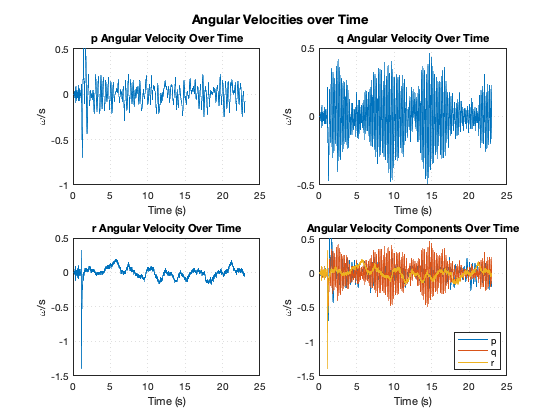

figure('NumberTitle', 'off', 'Name', 'Angular Velocities over Time');
sgtitle('Angular Velocities over Time','fontweight','bold')
subplot(2,2,1)
comparePlot(rt_tout,[pout'])
LabelPlot('p Angular Velocity Over Time', '\omega/s', 'Time (s)')

subplot(2,2,2)
comparePlot(rt_tout,[qout'])
LabelPlot('q Angular Velocity Over Time', '\omega/s', 'Time (s)')

subplot(2,2,3)
comparePlot(rt_tout,[rout'])
LabelPlot('r Angular Velocity Over Time', '\omega/s', 'Time (s)')

subplot(2,2,4)
comparePlot(rt_tout, [pout'; qout'; rout'])
LabelPlot('Angular Velocity Components Over Time', '\omega/s', 'Time (s)')
legend('p', 'q','r', 'Location', 'southeast')

## Plot Roll-Pitch-Yaw Angles

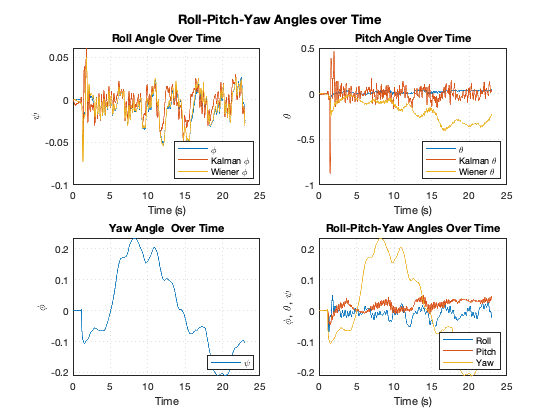

figure('NumberTitle', 'off', 'Name', 'Roll-Pitch-Yaw Angles over Time');
sgtitle('Roll-Pitch-Yaw Angles over Time','fontweight','bold')
subplot(2,2,1)
comparePlot(rt_tout,[phi_out'; phiK'; phiW'])
LabelPlot('Roll Angle Over Time', '\psi', 'Time (s)')
legend('\phi', 'Kalman \phi', 'Wiener \phi', 'Location', 'southeast')

subplot(2,2,2)
comparePlot(rt_tout,[theta_out'; thetaK'; thetaW'])
LabelPlot('Pitch Angle Over Time', '\theta', 'Time (s)')
legend('\theta', 'Kalman \theta', 'Wiener \theta', 'Location', 'southeast')

subplot(2,2,3)
comparePlot(rt_tout,[psi_out'])
LabelPlot('Yaw Angle  Over Time', '\phi', 'Time')
legend('\psi', 'Location', 'southeast')

subplot(2,2,4)
comparePlot(rt_tout,[phi_out'; theta_out'; psi_out'])
LabelPlot('Roll-Pitch-Yaw Angles Over Time', '\phi, \theta, \psi', 'Time (s)')
legend('Roll', 'Pitch', 'Yaw', 'Location', 'southeast')

## Plot Accelerations

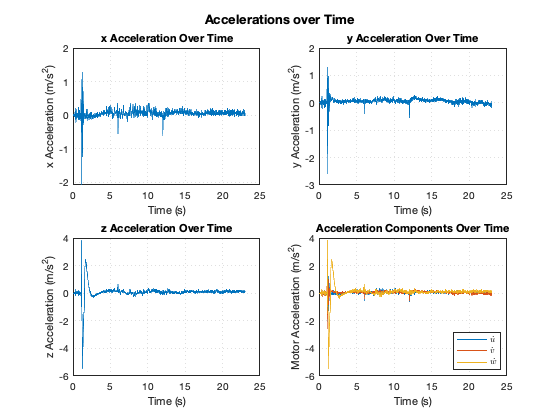

figure('NumberTitle', 'off', 'Name', 'Accelerations over Time');
sgtitle('Accelerations over Time','fontweight','bold')
subplot(2,2,1)
plot(rt_tout,du_out)
LabelPlot('x Acceleration Over Time', 'x Acceleration (m/s^2)', 'Time (s)')

subplot(2,2,2)
plot(rt_tout,dv_out)
LabelPlot('y Acceleration Over Time', 'y Acceleration (m/s^2)', 'Time (s)')

subplot(2,2,3)
plot(rt_tout,dw_out)
LabelPlot('z Acceleration Over Time', 'z Acceleration (m/s^2)', 'Time (s)')

subplot(2,2,4)
comparePlot(rt_tout, [du_out'; dv_out'; dw_out'])
LabelPlot('Acceleration Components Over Time', 'Motor Acceleration (m/s^2)', 'Time (s)')
legend('$\dot{u}$', '$\dot{v}$','$\dot{w}$', 'Location', 'southeast', 'Interpreter', 'latex')

## Plot Velocities

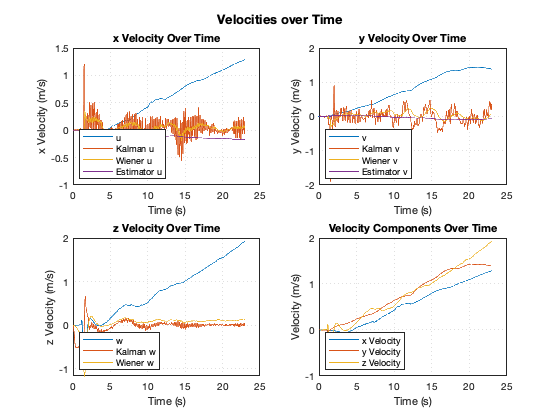

figure('NumberTitle', 'off', 'Name', 'Velocities over Time');
sgtitle('Velocities over Time','fontweight','bold')
subplot(2,2,1)
comparePlot(rt_tout,[u_out'; uK'; uW'; uE'])
LabelPlot('x Velocity Over Time', 'x Velocity (m/s)', 'Time (s)')
legend('u', 'Kalman u', 'Wiener u', 'Estimator u', 'Location', 'southwest')

subplot(2,2,2)
comparePlot(rt_tout,[v_out'; vK'; vW'; vE'])
LabelPlot('y Velocity Over Time', 'y Velocity (m/s)', 'Time (s)')
legend('v', 'Kalman v', 'Wiener v', 'Estimator v', 'Location', 'southwest')

subplot(2,2,3)
comparePlot(rt_tout,[w_out'; wK'; wW'])
LabelPlot('z Velocity Over Time', 'z Velocity (m/s)', 'Time (s)')
legend('w', 'Kalman w', 'Wiener w', 'Location', 'southwest')

subplot(2,2,4)
comparePlot(rt_tout,[u_out'; v_out'; w_out'])
LabelPlot('Velocity Components Over Time', 'Velocity (m/s)', 'Time (s)')
legend('x Velocity', 'y Velocity','z Velocity', 'Location', 'southwest')

## Plot Positions

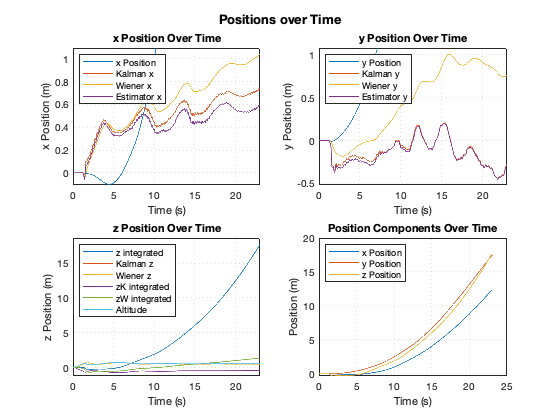

figure('NumberTitle', 'off', 'Name', 'Positions over Time');
sgtitle('Positions over Time','fontweight','bold')
subplot(2,2,1)
comparePlot(rt_tout,[x_out'; xK'; xW'; xE'])
LabelPlot('x Position Over Time', 'x Position (m)', 'Time (s)', [0 secs axisLimits([ xK'; xW'])])
legend('x Position', 'Kalman x', 'Wiener x', 'Estimator x', 'Location', 'northwest')

subplot(2,2,2)
comparePlot(rt_tout,[y_out'; yK'; yW'; yE'])
LabelPlot('y Position Over Time', 'y Position (m)', 'Time (s)', [0 secs axisLimits([ yK'; yW'])])
legend('y Position','Kalman y', 'Wiener y', 'Estimator y', 'Location', 'northwest')

subplot(2,2,3)
comparePlot(rt_tout,[z_out'; -zK'; -zW'; zKi'; zWi'; Alt'])
LabelPlot('z Position Over Time', 'z Position (m)', 'Time (s)', [0 secs axisLimits([z_out'; zK'+1.15; zW'+1.15; Alt'])])
legend('z integrated','Kalman z', 'Wiener z', 'zK integrated', 'zW integrated', 'Altitude', 'Location', 'northwest')

subplot(2,2,4)
comparePlot(rt_tout,[x_out'; y_out'; z_out'])
LabelPlot('Position Components Over Time', 'Position (m)', 'Time (s)')
legend('x Position', 'y Position','z Position', 'Location', 'northwest')

## Plot Altitude

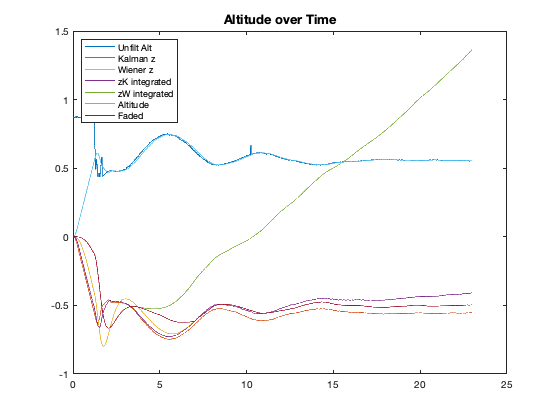

figure('NumberTitle', 'off', 'Name', 'Altitude over Time');
sgtitle('Altitude over Time','fontweight','bold')
comparePlot(rt_tout,[AltUnfilt';zK'; zW'; zKi'; zWi'; Alt'; zB'])
legend('Unfilt Alt', 'Kalman z', 'Wiener z', 'zK integrated', 'zW integrated', 'Altitude', 'Faded', 'Location', 'northwest')

## Plot Motor Speeds

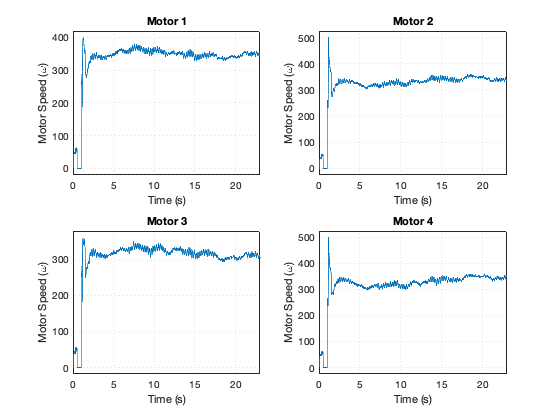

figure('NumberTitle', 'off', 'Name', 'Motor Speeds over Time');
subplot(2,2,1)
plot(rt_tout, motor1)
LabelPlot('Motor 1', 'Motor Speed (\omega)', 'Time (s)', [0 secs axisLimits(motor1)])

subplot(2,2,2)
plot(rt_tout, motor2)
LabelPlot('Motor 2', 'Motor Speed (\omega)', 'Time (s)', [0 secs axisLimits(motor2)])

subplot(2,2,3)
plot(rt_tout, motor3)
LabelPlot('Motor 3', 'Motor Speed (\omega)', 'Time (s)', [0 secs axisLimits(motor3)])

subplot(2,2,4)
plot(rt_tout, motor4)
LabelPlot('Motor 4', 'Motor Speed (\omega)', 'Time (s)', [0 secs axisLimits(motor4)])

## Plot TEAR

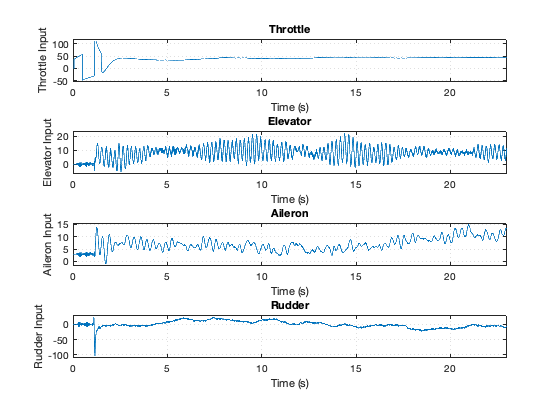

figure('NumberTitle', 'off', 'Name', 'TEAR over Time');
subplot(4,1,1)
comparePlot(rt_tout, [throttle'])
LabelPlot('Throttle', 'Throttle Input', 'Time (s)', [0 secs axisLimits([throttle'])])

subplot(4,1,2)
comparePlot(rt_tout, [elevator'])
LabelPlot('Elevator', 'Elevator Input', 'Time (s)', [0 secs axisLimits([elevator'])])

subplot(4,1,3)
comparePlot(rt_tout, [aileron'])
LabelPlot('Aileron', 'Aileron Input', 'Time (s)', [0 secs axisLimits([aileron'])])

subplot(4,1,4)
comparePlot(rt_tout, [rudder'])
LabelPlot('Rudder', 'Rudder Input', 'Time (s)', [0 secs axisLimits([rudder'])])

## Test

Ct = 0.0107;
rho = 1.22495238083;
D = 0.066;
b = 0.0441;
g = 9.81;
m = 0.063;
ispeed = sqrt((0.25*g)/(4*rho*Ct*D^4));

## Functions

function  LabelPlot(Title, y, x, Limits)
    if nargin < 4
        Limits = 1;
    end
    title(Title)
    xlabel(x)
    ylabel(y)
    grid on
    set(gca,'GridLineStyle', ':')
    if nargin == 4
        axis(Limits)
    end
end

function comparePlot(x, Ys) 
    [m n] = size(Ys);
    for i = 1:m
        plot(x, Ys(i,:))
        hold on;
    end
end

function leg = createLegendVec(starttimes)
    for i = 1:length(starttimes)
       leg(i) = cellstr(append('Minute ', string(starttimes(i))));
    end
end

function minmax = axisLimits(vecs) %for determining the axis limits. adds 5% of the range to the limits 
    axisMin = min(vecs,[],'all');
    axisMax = max(vecs,[],'all');
    window = range([axisMin axisMax]);
    axisMin = axisMin - window*0.05;
    axisMax = axisMax + window*0.05;
    minmax = [axisMin axisMax];
end